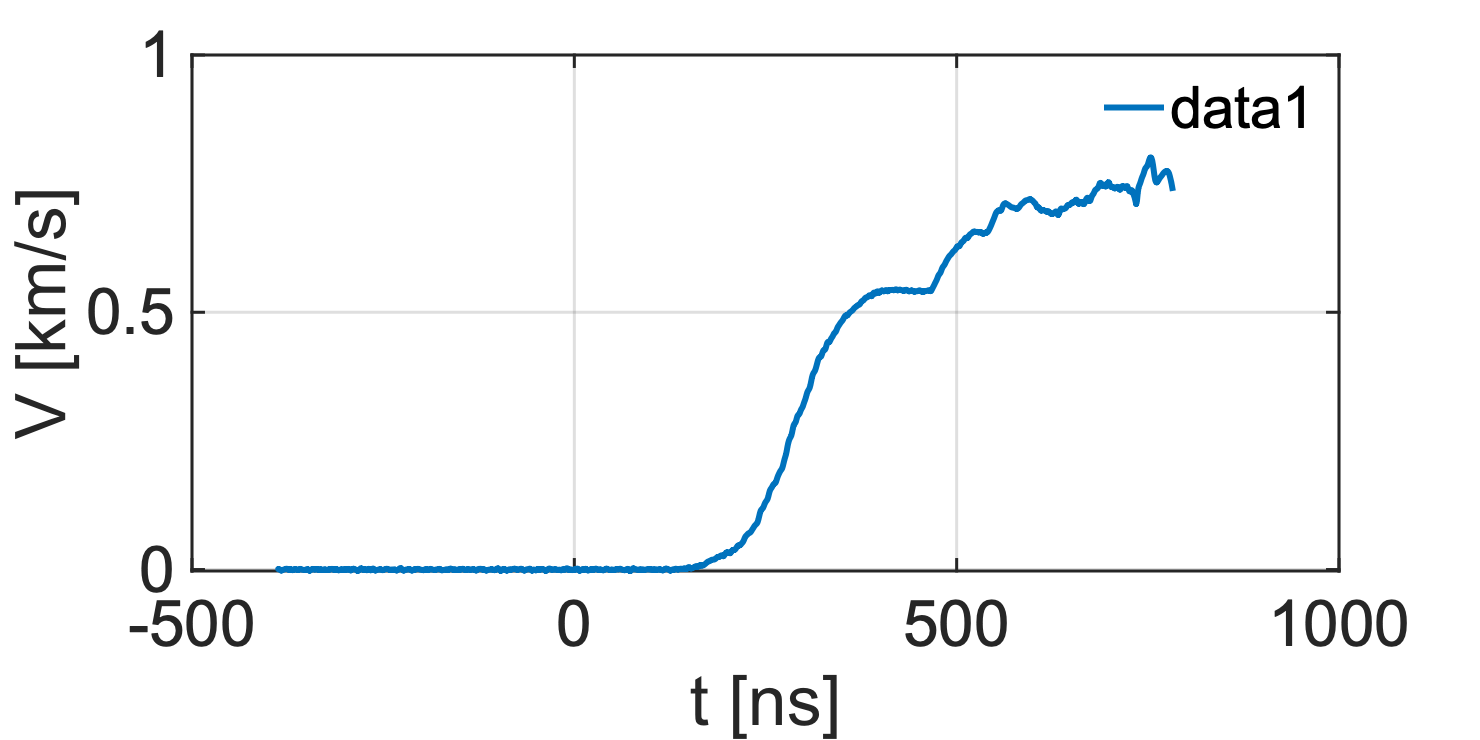

clc; close all; clear;

% This code plot sthe raw and integrated signals from the PDV diagnostics

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN group/Data/Z/MARZ/Shots/MARZ1_z3697/DriverTargetCoupling/ProcessedVelocimetry/z3697_PDV_waveforms/');


fname = 'z3697_PDV_A1.txt';

data = dlmread([inDir fname]);


figure
plot(data(:,1)-2800,data(:,2)/1e3,LineWidth=3)
xlabel('t [ns]'); ylabel('V [km/s]')
formatPlots(900,2); grid()

# For POP - Plot the Raw PDV Signals for each array

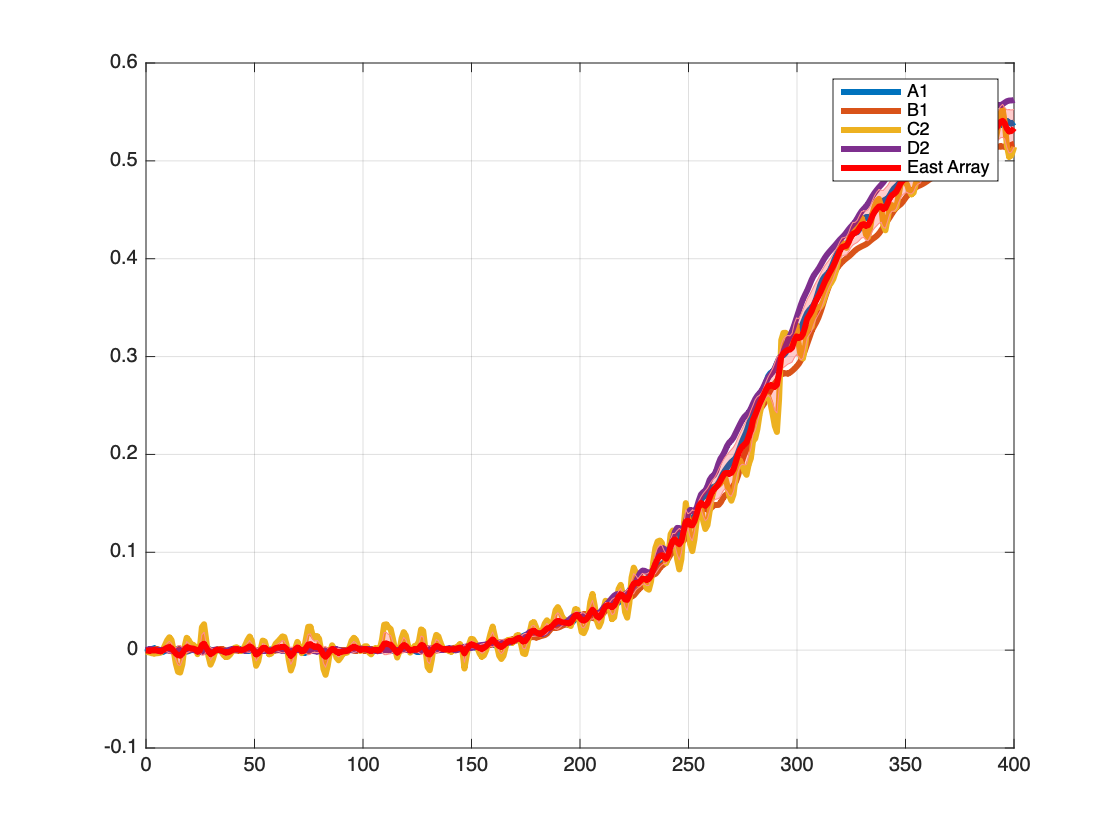

clc; clear;

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN group/Data/Z/MARZ/Shots/MARZ1_z3697/DriverTargetCoupling/ProcessedVelocimetry/z3697_PDV_waveforms/');

fnames_east = {'A1', 'B1', 'C2', 'D2'}; 

fnames_west = {'F1', 'G2', 'H2'}; 


f1 = figure(); f2 = figure();

for ii = 1:numel(fnames_east)
    fname = ['z3697_PDV_' fnames_east{ii} '.txt'];
    data = dlmread([inDir fname]);
    t = data(:,1); u = data(:,2);
    V{ii} = u((t > 2700) & (t < 3300)); % m/s
    figure(f1);
    plot(t((t > 2700) & (t < 3300))-2800,V{ii}/1e3,DisplayName=fnames_east{ii},LineWidth=3); hold on;
end

% avg. signal
V_east = 0.25 * (V{1} + V{2} + V{3} + V{4});
% std
Vsd = 0 * V_east;
for ii = 1:numel(fnames_east)
    Vsd = Vsd + (V{ii} - V_east).^2;
end
Vsd_east = sqrt(1/numel(fnames_east)) * sqrt(Vsd);

t = t((t > 2700) & (t < 3300))-2800;

shadedErrorBar(t,V_east/1e3,Vsd_east/1e3,'lineProps',{'Color','r','HandleVisibility','off'}); hold on;
plot(t,V_east/1e3,LineWidth=3,DisplayName='East Array',color='r'); hold on;
xlim([0,400]); grid(); legend();

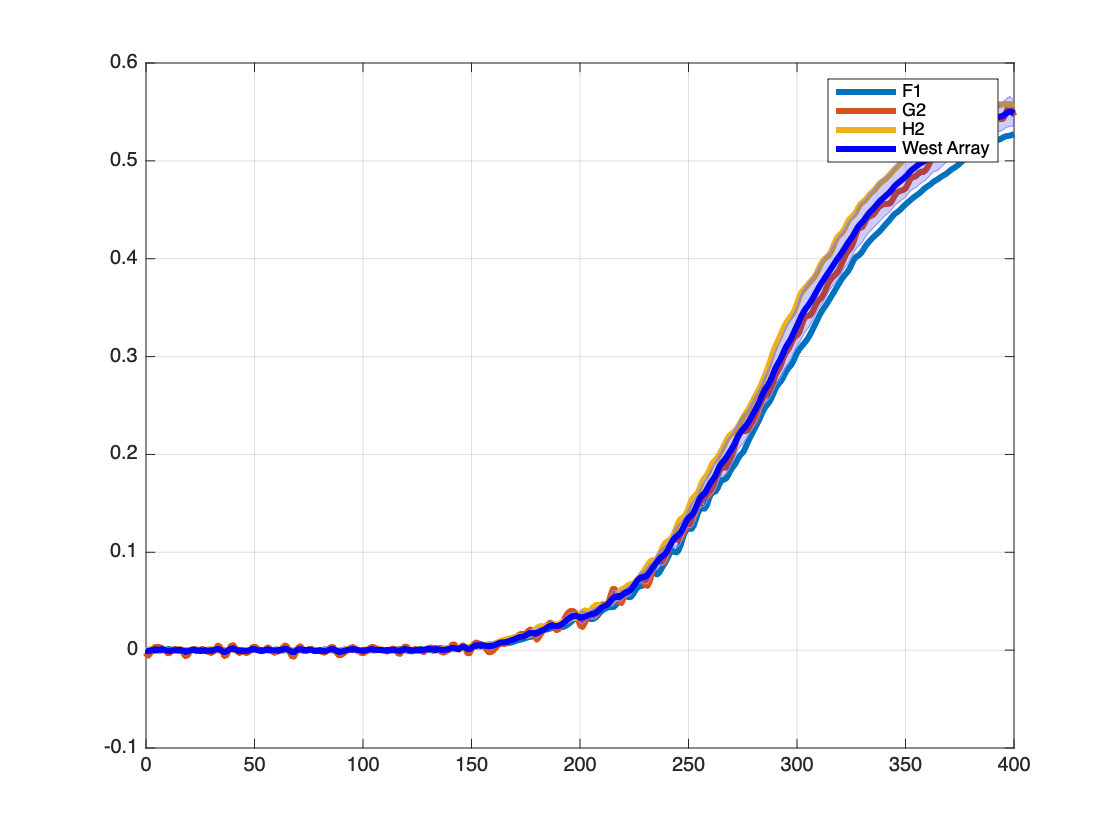




for ii = 1:numel(fnames_west)
    fname = ['z3697_PDV_' fnames_west{ii} '.txt'];
    data = dlmread([inDir fname]);
    t = data(:,1); u = data(:,2);
    V{ii} = u((t > 2700) & (t < 3300)); % m/s
    figure(f2);
    plot(t((t > 2700) & (t < 3300))-2800,V{ii}/1e3,DisplayName=fnames_west{ii},LineWidth=3); hold on;
end

% avg. signal
V_west = 0.25 * (V{1} + V{2} + V{3} + V{4});

% std
Vsd = 0 * V_west;
for ii = 1:numel(fnames_west)
    Vsd = Vsd + (V{ii} - V_west).^2;
end
Vsd_west = sqrt(1/numel(fnames_west)) * sqrt(Vsd);


t = t((t > 2700) & (t < 3300))-2800;

shadedErrorBar(t,V_west/1e3,Vsd_west/1e3,'lineProps',{'Color','b','HandleVisibility','off'})
plot(t,V_west/1e3,LineWidth=3,DisplayName='West Array',Color='b')
xlim([0,400]); grid(); legend();

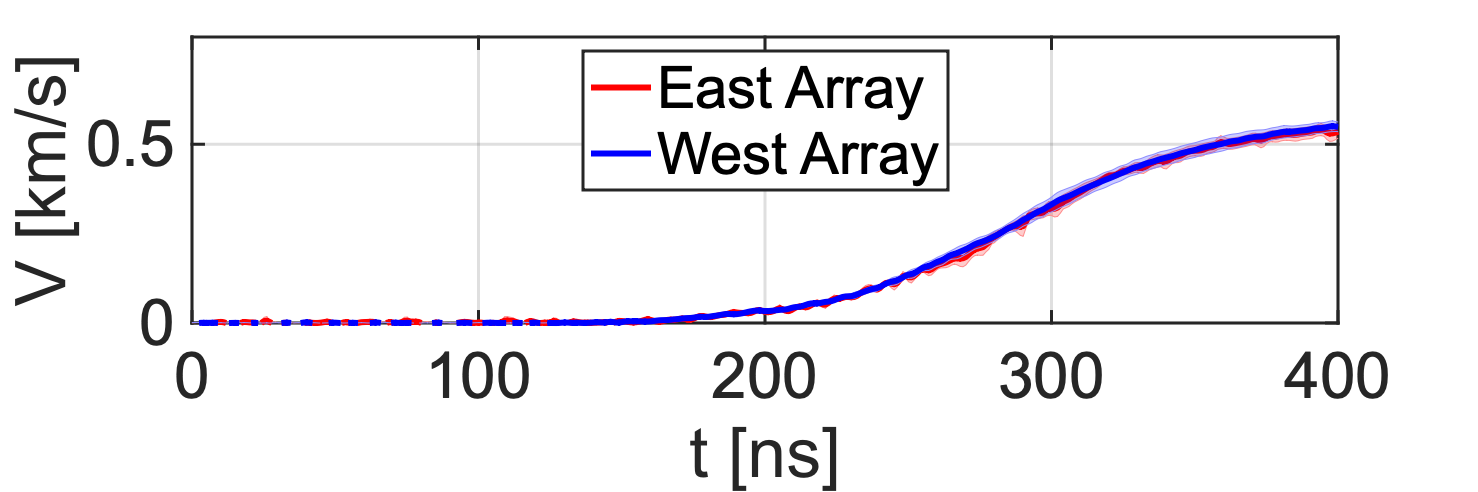


figure

shadedErrorBar(t,V_east/1e3,Vsd_east/1e3,'lineProps',{'Color','r','HandleVisibility','off'}); hold on;
plot(t,V_east/1e3,LineWidth=3,DisplayName='East Array',color='r'); hold on;


shadedErrorBar(t,V_west/1e3,Vsd_west/1e3,'lineProps',{'Color','b','HandleVisibility','off'})
plot(t,V_west/1e3,LineWidth=3,DisplayName='West Array',Color='b')
xlabel('t [ns]'); ylabel('V [km/s]')
xlim([0,400]); 
formatPlots(900,3); grid(); ylim([0,0.8])
legend(Location="north",box='on')

saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');

saveas(gcf,[saveDir,'z3697_PDV.png']);

## PDV Current Signal from all three shots

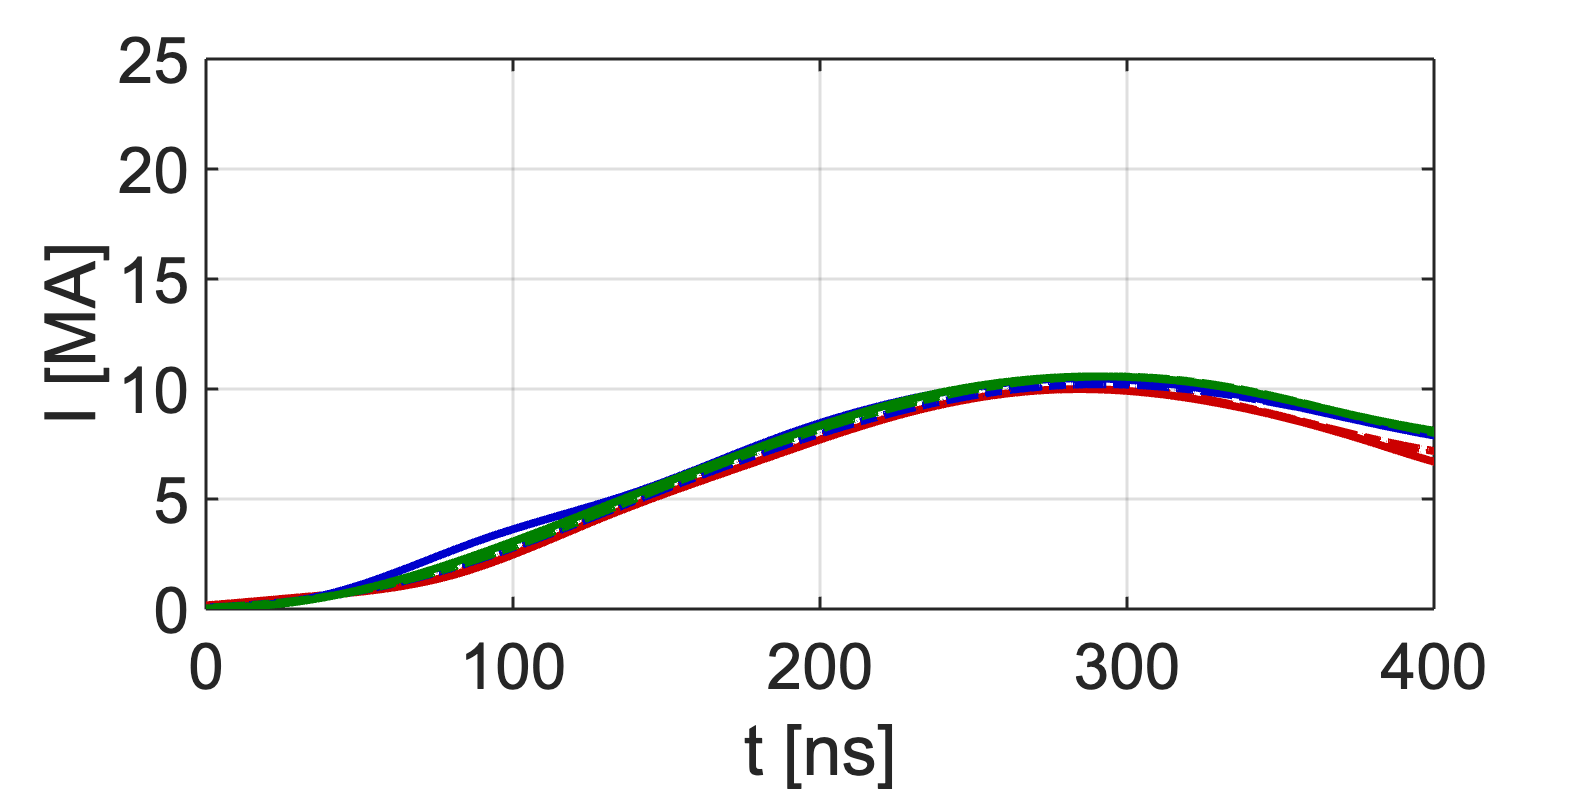

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/PDV/');

% marz 1
shot_id = 'z3697';
fname = ['current-unfold-mean-' upper(shot_id)];

data_east = dlmread([inDir shot_id '/' fname 'East.txt']);
data_west = dlmread([inDir shot_id '/' fname 'West.txt']);

figure
plot(data_east(:,1)-2800,data_east(:,2),LineWidth=4,HandleVisibility='off',color=[0.8 0 0 0.7]); hold on;
plot(data_west(:,1)-2800,data_west(:,2),LineWidth=4,Linestyle='-.',HandleVisibility='off',color=[0.8 0 0 0.7]);

% marz2
shot_id = 'z3778';
fname = ['current-unfold-mean-' upper(shot_id)];

data_east = dlmread([inDir shot_id '/' fname 'East.txt']);
data_west = dlmread([inDir shot_id '/' fname 'West.txt']);

plot(data_east(:,1)-2800,data_east(:,2),LineWidth=4,HandleVisibility='off',color=[0 0 0.8 0.7]); hold on;
plot(data_west(:,1)-2800,data_west(:,2),LineWidth=4,Linestyle='-.',HandleVisibility='off',color=[0 0 0.8 0.7]);


% marz3

shot_id = 'z3781';
fname = ['current-unfold-mean-' upper(shot_id)];

data_east = dlmread([inDir shot_id '/' fname 'East.txt']);
data_west = dlmread([inDir shot_id '/' fname 'West.txt']);


plot(data_east(:,1)-2800,data_east(:,2),LineWidth=4,HandleVisibility='off',color=[0 0.5 0 0.7]); hold on;
plot(data_west(:,1)-2800,data_west(:,2),LineWidth=4,Linestyle='-.',HandleVisibility='off',color=[0 0.5 0 0.7]);

formatPlots(900,2);
xlabel('t [ns]'); ylabel('I [MA]');
xlim([0,400]); ylim([0,25])
grid();
legend('off');


% saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');

% saveas(gcf,[saveDir,'z3697_PDV.png']);